% sys = load("sys.mat").sys

LV_affine = load("LV_affine.mat"').LV_array

PSS with 13 States, 11 Outputs, 10 Inputs, Continuous System.               
The PSS consists of the following blocks:                                   
  v_x: Gridded real, 4037 points in [95.9,1.77e+03], rate bounds [5.4,36.4].


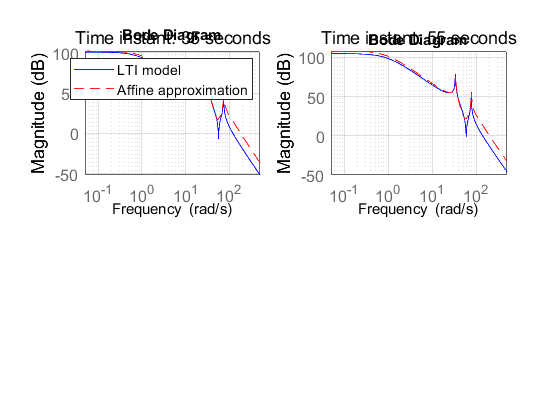




time_index =@(t) find(raw{18}.Values.Time == t);
figure
subplot(2,2,1);
bodemag(sys{1}(2,1),'b-');grid
xlim([5*10^-2 5*10^2])
xticks([10^-2 10^-1 10^-0 10^1 10^2])
hold on
bodemag(LV_affine.Data(2,end,time_index(35),1),'r--')
subtitle('Time instant: 35 seconds');
legend('LTI model','Affine approximation')
ax = gca;
ax.FontSize = 12;

time_index =@(t) find(raw{18}.Values.Time == t);
subplot(2,2,2);
bodemag(sys{2}(2,1),'b-');grid
xlim([5*10^-2 5*10^2])
xticks([10^-2 10^-1 10^-0 10^1 10^2])
hold on
bodemag(LV_affine.Data(2,end,time_index(55),1),'r--')
subtitle('Time instant: 55 seconds');
ax = gca;
ax.FontSize = 12;


% subplot(2,2,3)
% bodemag(sys{3}(2,1),'b-');grid
% xlim([5*10^-2 5*10^2])
% xticks([10^-2 10^-1 10^-0 10^1 10^2])
% hold on
% bodemag(LV_affine.Data(2,end,time_index(75),1),'r--')
% ax = gca;
% ax.FontSize = 12;
% subtitle('Time instant: 75 seconds');

